% Get training images

flower_ds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');
[trainImgs,testImgs] = splitEachLabel(flower_ds,0.6);
numClasses = numel(categories(flower_ds.Labels));
 

% Create a network by modifying AlexNet

net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;
 

% Set training algorithm options

options = trainingOptions('sgdm','InitialLearnRate', 0.001);
 

% Perform training

[flowernet,info] = trainNetwork(trainImgs, layers, options);

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　２７．０３％　｜　　４．４７６１　｜　　０．００１０　｜
｜　　３０　｜　　　３０　｜　　　　　００：００：０５　｜　　１００．００％　｜　２．５２６１ｅ－０６　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


 

% Use trained network to classify test images

testpreds = classify(flowernet,testImgs)

testpreds = 25×1 categorical 数组
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     flw1 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 
     fw2 


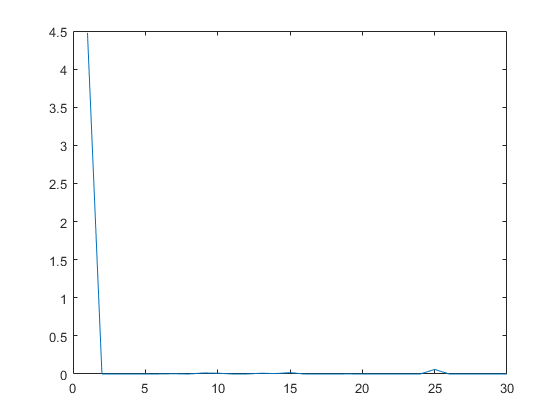


%x显示loss 补充查看
plot(info.TrainingLoss)

flwrActual = testImgs.Labels;

numCorrect = nnz(testpreds == flwrActual)

numCorrect = 25


fracCorrect = numCorrect/numel(testpreds)

fracCorrect = 1

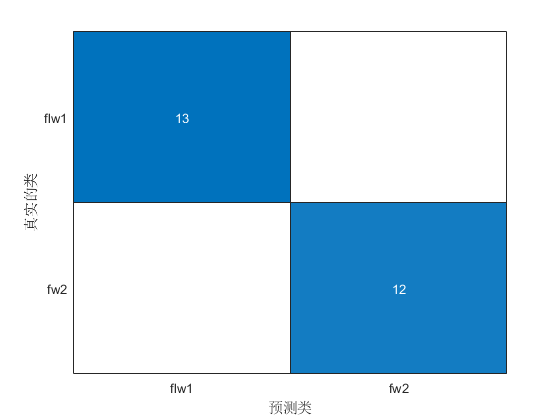

ans =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  显示 所有属性



confusionchart(testImgs.Labels,testpreds)